# Son 1:  Signal monotone Sinus 440 Hz

%% Exemple avec un signal simple
% le but est de s'introduire aux outils de tratement du signal avec matlab 
% ces outils sont notament comment généner un bruit ajouter une signal gaussien
% ainsi que diverses méthodes de filtration.

Le premier signal traité as pour but  d'etre simple. Sa simplicité va perettre de mieu comprendre les subtilitées entre les diverses implémentations de filtres ainsi que les nuances entre elles. 

Le signal ne sera pas subdivisé à cause du faite qu'il est peu pertinent de subdiviser un signal monotone. 

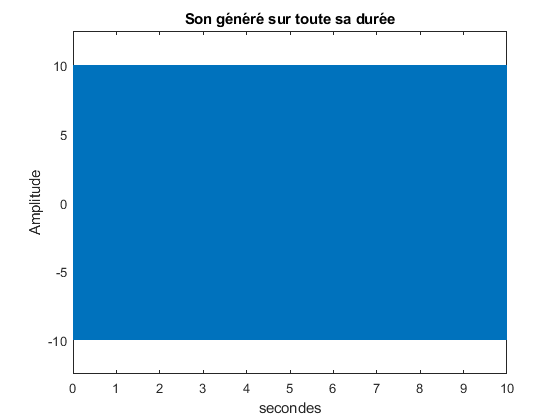


clear;
close all;
clc;

% -------------init vars ----------------------
frequencyLimits = [0 24000];

%% Création d'un signal
amp=10 ;
fs=44000;  % sampling rate
duration=10; % secondes
freq=440; %[Hz]
t=0:1/fs:duration;
son_1=amp*sin(2*pi* freq*t);
%sound(son_1,fs); % écouter le son

figure
plot(t,son_1);
title('Son généré sur toute sa durée')
xlabel('secondes');
ylabel('Amplitude');
ylim([-amp-0.25*amp amp+0.25*amp])

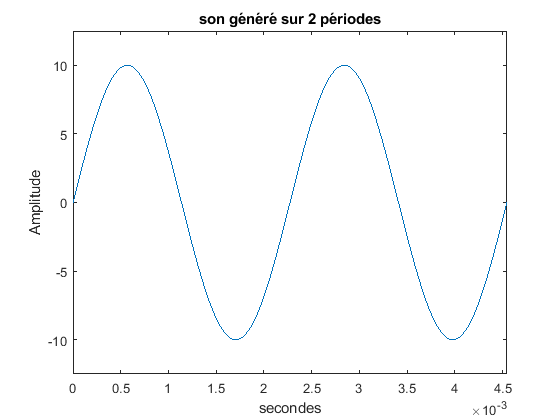


figure
plot(t,son_1);
title('son généré sur 2 périodes')
xlim([0 2*(1/freq)])
ylim([-amp-0.25*amp amp+0.25*amp])
xlabel('secondes');
ylabel('Amplitude');

Pour analyser nos signaux dans le câdre de ce projet, deux outils d'analyse seront utilisés.

 La transformé de Fourier discrete implémenté avec l'algorythme de la fonction fft() [Fast Fourrier Transform]. Le deuxième outil est l'analyse spectrale. Deux fonctions sur mesures ont étés faites pour faire l'analyse et afficher les résultats au cours de ce projet.

L'analyse spectrale permet de voir la densité et la distribution de la  puissance du signal en fonction de la fréquence tandis que la la fft permet de voir la distribution de fréquences dans le signal.

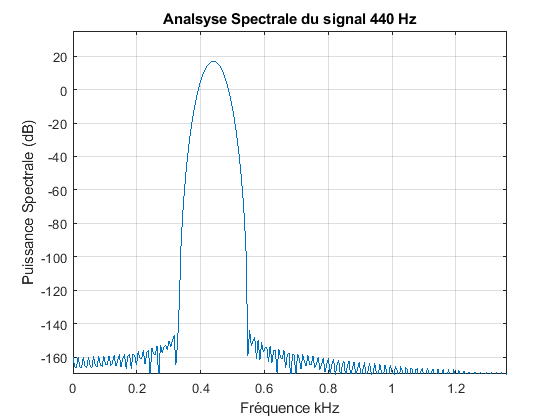

figure
SpectralAnalyser(son_1,fs,frequencyLimits,0,[0 15]);
xlim([0 1.36])
ylim([-170 35])
title('Analsyse Spectrale du signal 440 Hz');

figure
fftPlotter(son_1,fs);

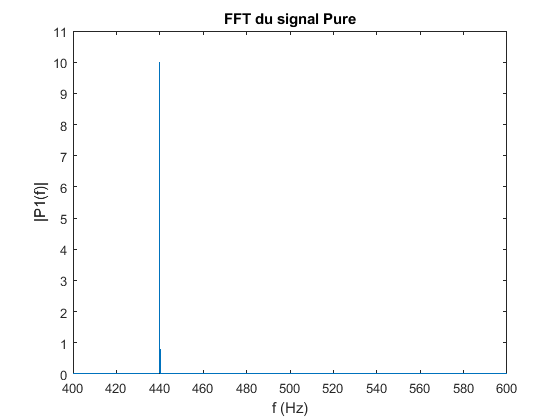

title('FFT du signal Pure')
xlabel('f (Hz)')
ylabel('|P1(f)|')

xlim([400 600])
ylim([0.00 11])

Un bruit blanc gaussien est définie par les la somme des définitions suivantes :

 **   -BRUIT BLANC:=** un bruit blanc est définie comme étant que les perturabtions sonts réparties                                               uniformméent sur l'ensemble des fréquences.

**Bruit Gaussien := **Est distribué selon une courbe de Loi Normale.

Afin d'ajouter un bruit blanc gaussien, la fonction awgn()  [Add white Gaussian noise to signal]  sera utiliser.

Les paramêtres de     la fonction sont :

        **out = awgn(input_signal,snr)**

**                Input_signal := le signal d'entrée**

**                SNR := signal-to-noise ratio**

Pour cet execrice un SNR arbitraire de 0.5 sera utilisé. le fait que SNR < 1 indique que les bruit est plus présent que le signal d'origin.

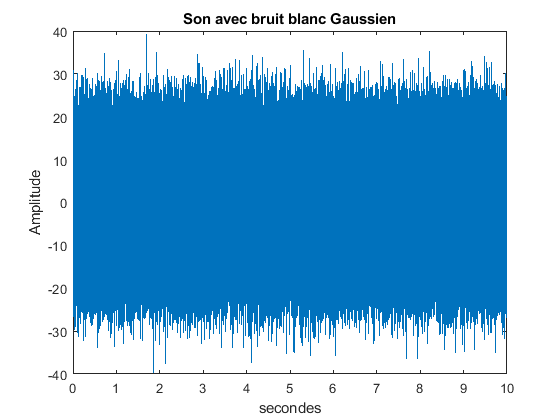

%% Ajout du bruit gaussien


range = 5;
SNR = 0.5;

son_avec_bruit = awgn(son_1, SNR,  'measured');


figure
plot(t,son_avec_bruit);
title('Son avec bruit blanc Gaussien');
xlabel('secondes');
ylabel('Amplitude');


figure
fftPlotter(son_avec_bruit,fs);

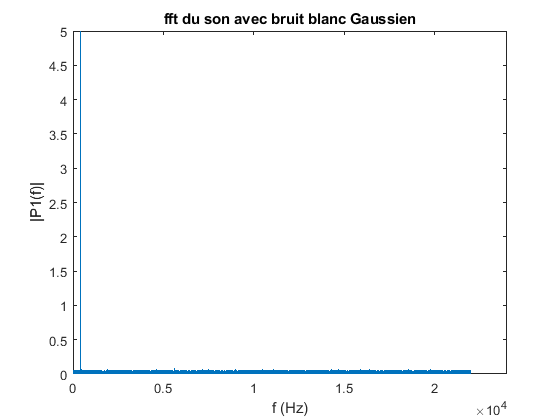

xlim([0 24000]);
ylim([0 5]);
title('fft du son avec bruit blanc Gaussien');


figure
fftPlotter(son_avec_bruit,fs);

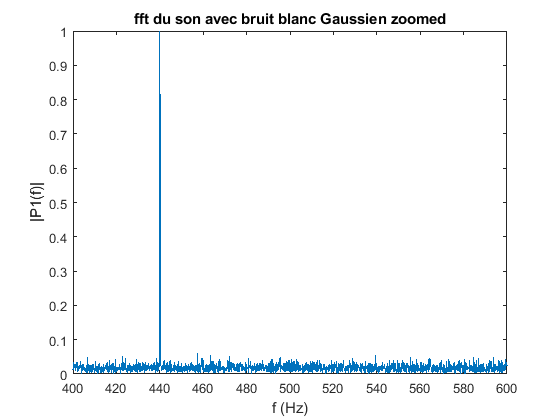

xlim([400 600]);
ylim([0 1]);
title('fft du son avec bruit blanc Gaussien zoomed');

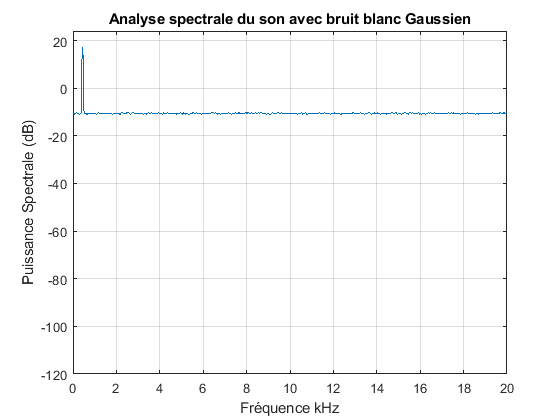


figure
SpectralAnalyser(son_avec_bruit,fs,frequencyLimits,0,[0 15]);
xlim([0 20])
ylim([-120 24])
title('Analyse spectrale du son avec bruit blanc Gaussien');

%sound(son_avec_bruit,fs);
%audiowrite('Block\son_avec_bruit.wav',son_avec_bruit,fs);

## Utilistion des filtres integés dans matlab 

%% Application d'un filtre simple (lowpass)

son_1_filtre_lowpass1 = lowpass(son_avec_bruit,1,fs);


figure
fftPlotter(son_1_filtre_lowpass1,fs);

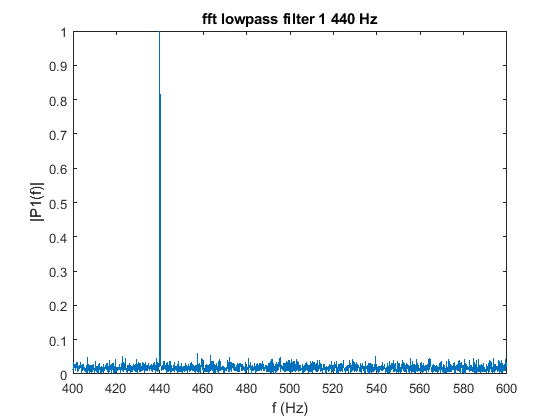

xlim([400 600]);
ylim([0 1]);
title('fft lowpass filter 1 440 Hz');

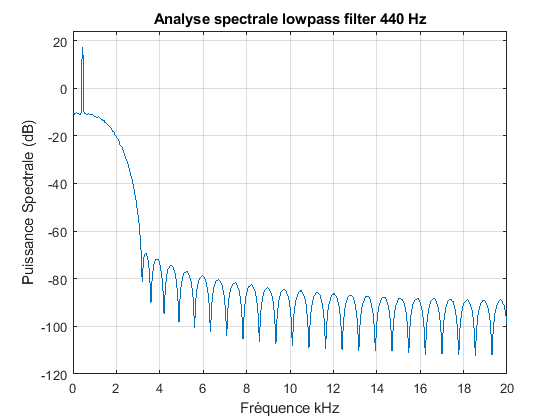


figure
SpectralAnalyser(son_1_filtre_lowpass1,fs,frequencyLimits,0,[0 15]);
xlim([0 20])
ylim([-120 24])
title('Analyse spectrale lowpass filter 440 Hz');


%sound(son_1_filtre_lowpass1,fs);
%audiowrite('Block\son_1_filtre_lowpass1.wav',son_1_filtre_lowpass1,fs);

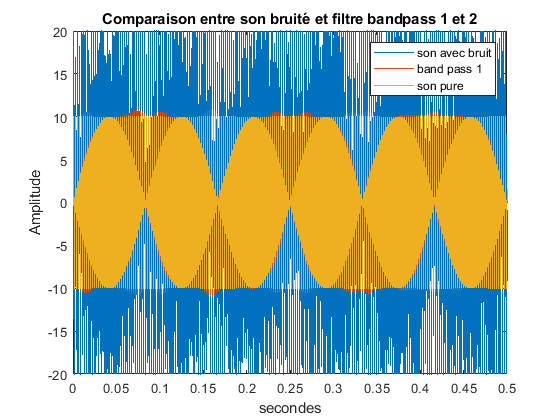

%% Filtre bandpass
%filters the input signal x using a lowpass filter with normalized passband frequency wpass in units of ? rad/sample. lowpass uses a minimum-order filter with a stopband attenuation of 60 dB and compensates for the delay introduced by the filter. If x is a matrix, the function filters each column independently.


%% Application d'un filtre Bandpass
% puisque le son original est d'une seule et unique fréquence, il est trivial de supposer qu'un filtre passeband avec une gamme de fréquence proche du signal original sera relativement efficace pour filtrer le bruit



bruit_1_filtre_bandpass = bandpass(son_avec_bruit,[freq-range freq+range],fs);



figure
    plot(t,son_avec_bruit);
    hold on    
    plot(t,bruit_1_filtre_bandpass)   
    plot(t,son_1);
    xlabel('secondes');
    ylabel('Amplitude');
    xlim([0 0.5])
    ylim([-amp-amp amp+amp])
    legend('son avec bruit','band pass 1','son pure')
    title('Comparaison entre son bruité et filtre bandpass 1 et 2')
    hold off;

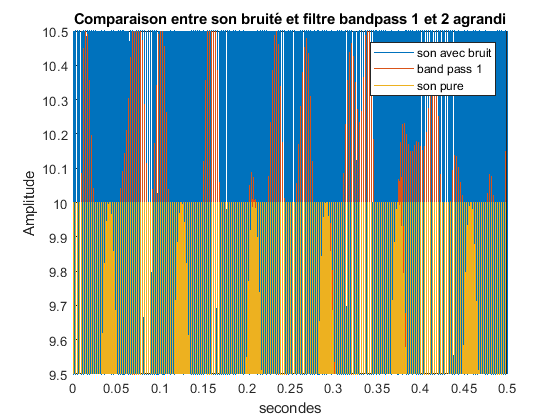


figure
    plot(t,son_avec_bruit);
    hold on
    plot(t,bruit_1_filtre_bandpass)
    plot(t,son_1);
    
    xlabel('secondes');
    ylabel('Amplitude')
    legend('son avec bruit','band pass 1','son pure')
    xlim([0 0.5])
    ylim([amp-0.5 amp+0.5])
    title('Comparaison entre son bruité et filtre bandpass 1 et 2 agrandi')
    hold off;

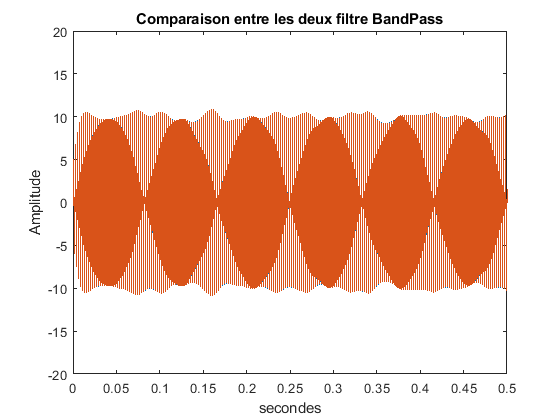



figure
SpectralAnalyser(bruit_1_filtre_bandpass,fs,frequencyLimits,0,[0 15]);
xlim([0 20])
ylim([-120 24])
title('Analyse spectrale bandpass filter 440 Hz');


   
%sound(bruit_1_filtre_bandpass,fs);
%audiowrite('Block\bruit_1_filtre_bandpass.wav',bruit_1_filtre_bandpass,fs);

Avec la dernière comparaison il facile de voir l'impact du filtre passbande sur le son bruité. En effet, la majorité de perturbation ont été retiré et ils serais encore possible d'en enlever d'avantage en modifiant légèrement le filtre passebande pour filter tout sauf la fréquence de 440 Hz. Pour avoir des résultats optimal. Utilisons les paramètres suivants.

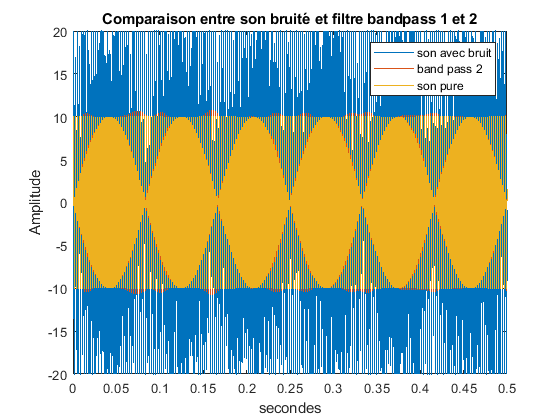

bruit_1_filtre_bandpass2 = bandpass(son_avec_bruit,[freq-1 freq+1],fs);


%plot(t,son_1);
plot(t,bruit_1_filtre_bandpass2);

%xlim([0 0.5])
%ylim([amp-0.5 amp+0.5])
hold on;
plot(t,bruit_1_filtre_bandpass);

title('Comparaison entre les deux filtre BandPass')

xlabel('secondes');
ylabel('Amplitude');
xlim([0 0.5])
ylim([-amp-amp amp+amp])

hold off;


figure
    plot(t,son_avec_bruit);
    hold on    
    plot(t,bruit_1_filtre_bandpass2)   
    plot(t,son_1);
    xlabel('secondes');
    ylabel('Amplitude');
    xlim([0 0.5])
    ylim([-amp-amp amp+amp])
    legend('son avec bruit','band pass 2','son pure')
    title('Comparaison entre son bruité et filtre bandpass 1 et 2')
    hold off;

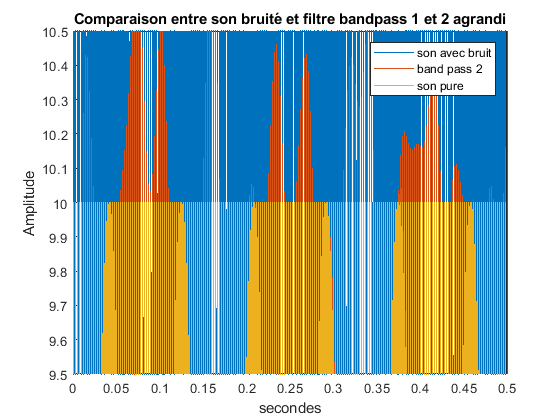


figure
    plot(t,son_avec_bruit);
    hold on
    plot(t,bruit_1_filtre_bandpass2)
    plot(t,son_1);
    
    xlabel('secondes');
    ylabel('Amplitude')
    legend('son avec bruit','band pass 2','son pure')
    xlim([0 0.5])
    ylim([amp-0.5 amp+0.5])
    title('Comparaison entre son bruité et filtre bandpass 1 et 2 agrandi')
    hold off;


%sound(bruit_1_filtre_bandpass2,fs);
%audiowrite('Block\bruit_1_filtre_bandpass2.wav',bruit_1_filtre_bandpass2,fs);

Malgré que le signal de sortie est suffisant filtré. Essayons d'aller plus loin. Les imperfections du signal de sortie sont probalblement du à l'effet de "ripple" des filtre appliqués. Afin de limiter cette effet essayons d'implémenter d'autres types de filtres pour voir leurs effets sur le signal de sortie.

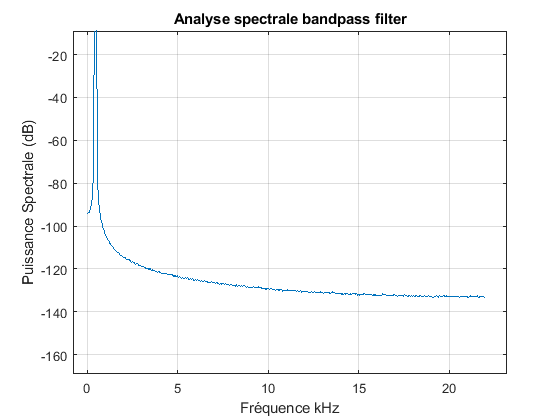


figure
    SpectralAnalyser(bruit_1_filtre_bandpass,fs,frequencyLimits,0,[0 15]);
    %xlim([0 20])
    %ylim([-120 24])
    title('Analyse spectrale bandpass filter');

En regardant l'analyse spectrale, nous pouvons supposser que les imperfections proviennent de la bande de transition entre la bande passante et la bande de atténué. Essyons alors un filtre de Chebychev pour améliorer la réponse.

Essayons un chebychev de type 2. le type 2 est utilisé car ce type va permettre une meilleur atténuation 

## Application d'un filtre Chebychev

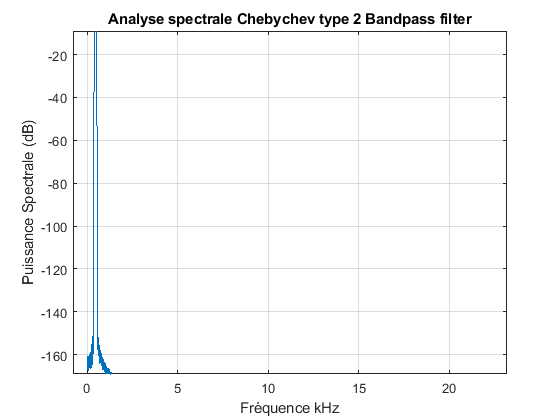

N      = 26;   % Order
Fstop1 = freq-1;  % First Stopband Frequency
Fstop2 = freq+1;  % Second Stopband Frequency
Astop  = 130;   % Stopband Attenuation (dB)

% Construct an FDESIGN object and call its CHEBY2 method.
h  = fdesign.bandpass('N,Fst1,Fst2,Ast', N, Fstop1, Fstop2, Astop, fs);
cheby2 = design(h, 'cheby2');

resCheb = filter(cheby2,son_avec_bruit);

figure
SpectralAnalyser(resCheb,fs,frequencyLimits,0,[0 15]);
title('Analyse spectrale Chebychev type 2 Bandpass filter')

%xlim([0 20])
%ylim([-120 24])

figure
fftPlotter(resCheb,fs)

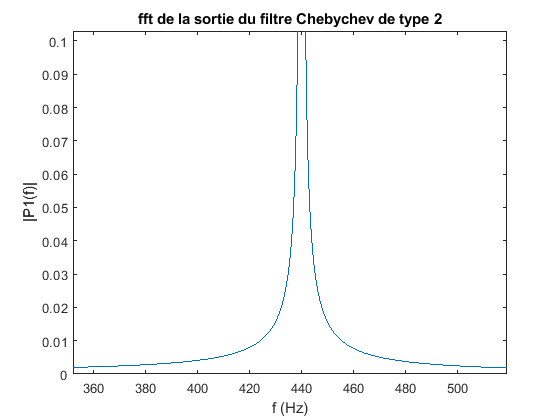

title('fft de la sortie du filtre Chebychev de type 2')
xlim([352 519])
ylim([0.0000 0.1030])


%sound(bruit_1_filtre_bandpass,fs);
%audiowrite('Block\bruit_1_filtre_bandpass.wav',bruit_1_filtre_bandpass,fs);

On peut voir que selon l'analyse spectral que la transiton entre la bande passante et la bande de atténué est beaucoup moins abrupte avec le filtre de chbychev.Les différences ne sont pas audibles avec le matériel disponible actuellement. 

Essayons donc  un filtre avec une plus grande vitesse de transision. avec exactement les memes paramêtres.

## Eliptic bandpass

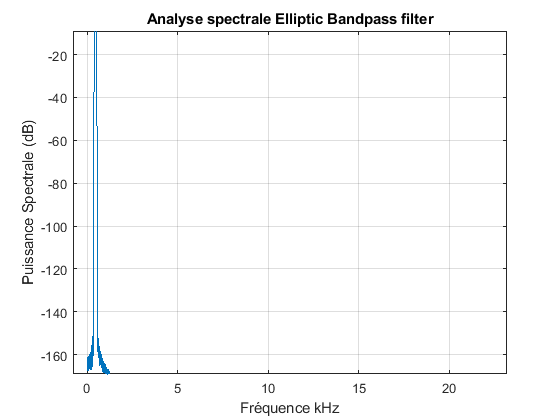



d = designfilt('bandpassiir','FilterOrder',N, ...
    'PassbandFrequency1',Fstop1,'PassbandFrequency2',Fstop2, ...
    'PassbandRipple',3, ...
    'StopbandAttenuation1',40,'StopbandAttenuation2',Astop, ...
    'SampleRate',fs);

resEllip= filter(d,son_avec_bruit);


figure
    SpectralAnalyser(resEllip,fs,frequencyLimits,0,[0 15]);
    title('Analyse spectrale Elliptic Bandpass filter')

  
figure
    fftPlotter(resEllip,fs);

    title(' Comparaison entre fft signaux chebychev 2 et Elliptique de même ordre')
    hold on
    fftPlotter(resCheb,fs)

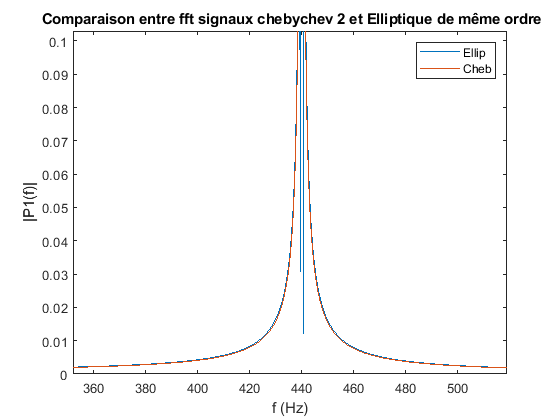

    xlim([352 519])
    ylim([0.0000 0.1030])
    legend('Ellip','Cheb')

   
%sound(resEllip,fs);
%audiowrite('Block\resEllip.wav',resEllip,fs);

Il est évident sur le dernier graphique que la vitesse de transition du filtre Elliptique est plus grande que celle edu filtre de type Chebychev.  

Puisque le signal est monotone, il serais peu intérant d'essayer des filtres de type Butterworth à cause de vitesse de transition lente. 

 Cependant, il est interessant d'essayer une filtre de type Peigne (Comb). Les filtres de type peigne ont comme caractéristique d'être implémenté via l'application d'un déphase du signal filtré. Ce déphasage est par rapport à lui même.

 Ce délais a pour effet de causer des interférences constructives et destructives. Il est important de noter que ce type de filtre n'est pas recommandé pour filtrer une gamme de fréqunce mais en faite une fréquence spécifique.

En effet, les filtres de type peignes sont une sous catégorie des filtres de type coup-bande.

Donc pour ce filtre spécifique, au lieu de filtrer le bruit gaussien, essayons de suprimer le signal de 440 Hz.

## Comb filter

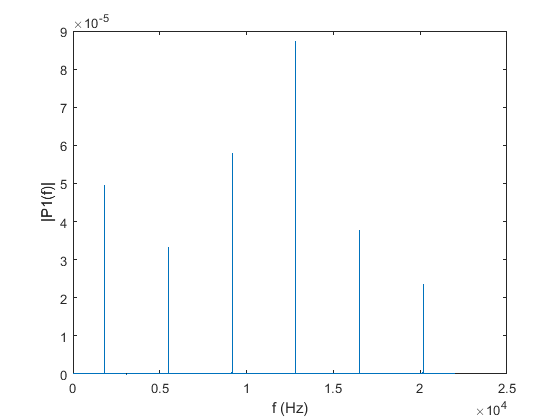



N     = 12;   % Order
BW    = freq;  % Bandwidth
Apass = 130;    % Bandwidth Attenuation

[b, a] = iircomb(N, BW/(fs/2), Apass, 'peak');
combFilt    = dfilt.df2(b, a);

resComb = filter(combFilt,son_avec_bruit);
figure
fftPlotter(resComb,fs);

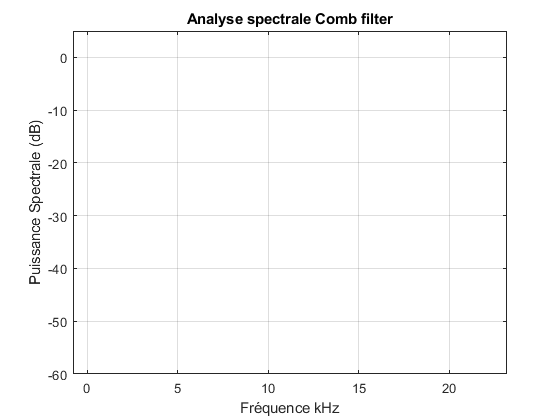


figure
SpectralAnalyser(resComb,fs,frequencyLimits,0,[0 15]);
ylim([-60 5])
title('Analyse spectrale Comb filter')

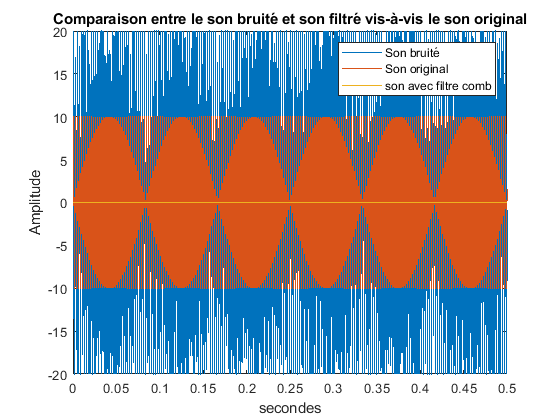


figure

plot(t,son_avec_bruit);
xlabel('secondes');
ylabel('Amplitude');
xlim([0 0.5])
ylim([-amp-amp amp+amp])


hold on;

plot(t,son_1);
plot(t,resComb);
legend('Son bruité','Son original','son avec filtre comb')
title('Comparaison entre le son bruité et son filtré vis-à-vis le son original')
hold off; 



%sound(resComb,fs);
%audiowrite('Block\resCom.wav',resComb,fs);

Le dernier filtre a bel et bien fonctionné comme prévue. Il a agit en filtre coupe bande à une fréquence de 440 Hz. À l'oreille est évident que le son de base a été atténué par rapport au bruit qui semble plus prononcé qu'au paravant.

Par contre, en ragardant la fft du signal filtré on peut voir que le déphasage a aussi isolé d'autres fréquences comme effet secondaire.

## HighPass filter

Un dernier type de filtre qui n'a pas été étudié, est le filtre pass haut. Il est évident avant même l'application de ce filtre que les résultats ne seront pas optimaux. La réponse pourquoi est la suivante:  

     la fréquence de 440 Hz se situe dans une gamme de fréquence qui est relativement basse. Un filtre qui ne laisse passer que les hautes fréquence aura les résultas suivants:

        1) [ freq < fréquence du signal]  le signal sera laissé passé mais le filtre va sussi conserver la mojorité de parasites.

        2) [ freq > fréquence du signal]  le signal sera filtré.


son_1_filtre_highPass1 = highpass(son_avec_bruit,freq,fs);




figure
fftPlotter(son_1_filtre_highPass1,fs);

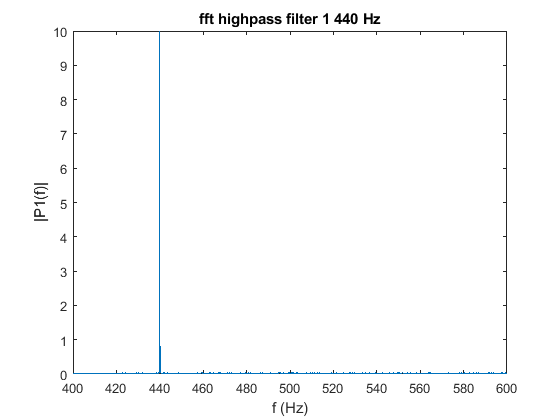

xlim([400 600]);
ylim([0 10]);
title('fft highpass filter 1 440 Hz');


%sound(son_1_filtre_highPass1 ,fs)
%audiowrite('Block\son_1_filtre_highPass1.wav',son_1_filtre_highPass1,fs);


son_1_filtre_highPass2 = highpass(son_avec_bruit,freq+20,fs);




figure
fftPlotter(son_1_filtre_highPass2,fs);

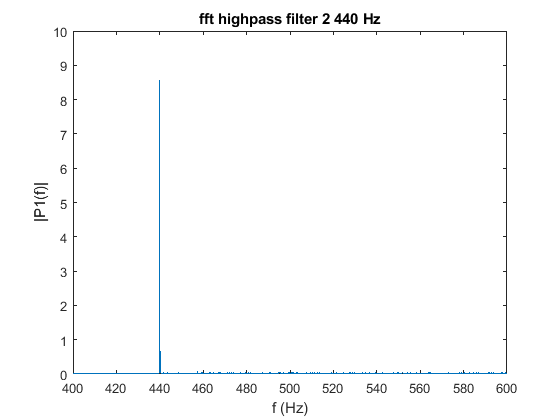

xlim([400 600]);
ylim([0 10]);
title('fft highpass filter 2 440 Hz');


%sound(son_1_filtre_highPass2 ,fs)
%audiowrite('Block\son_1_filtre_highPass2.wav',son_1_filtre_highPass2,fs);


son_1_filtre_highPass3 = highpass(son_avec_bruit,freq+50,fs);




figure
    fftPlotter(son_1_filtre_highPass3,fs);

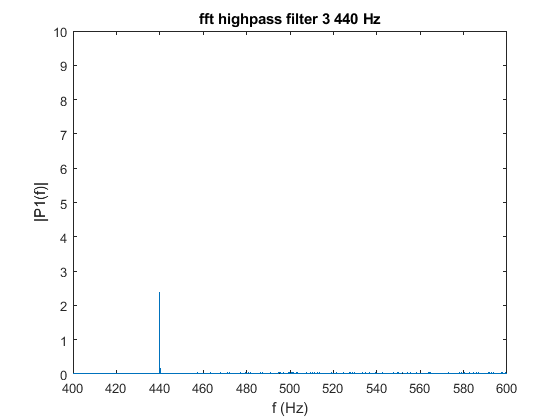

    xlim([400 600]);
    ylim([0 10]);
    title('fft highpass filter 3 440 Hz');


%sound(son_1_filtre_highPass3 ,fs)
%audiowrite('Block\son_1_filtre_highPass3.wav',son_1_filtre_highPass3,fs);

    En regardant les grapique de fft Highpass 1,2 et 3, il est facil de voir que le signal à conserver diminue rapidement tandis que le bruit quand à lui reste fortement présent.     

Maintenant qu'il a été démontré que les filtre passes haute sont inutiles pour la problématique de ce projet. Les filtres de ce type ne seront plus étudié dans le câdre de ce projet.

## Conclusion 

En comparant ce qui a été démontré avec les filtres testés prédament. Il est plustot facile de traiter un son lorque nous connaissons les caracteristique du signal à isoler. Dans ce cas si, il est facil d'isoler un son à une fréquence de 440 Hz eavec un filtre passeBande qui ne laisse passer cette dréquence spécifique tout en enlevant toutes les autres frequences perceptibles à l'oreille humaine.

Le prochain signal devra être un bruit avec des multiple fréquences ce qui devrait rendre la tâche d'isoler le signal plus ardu.